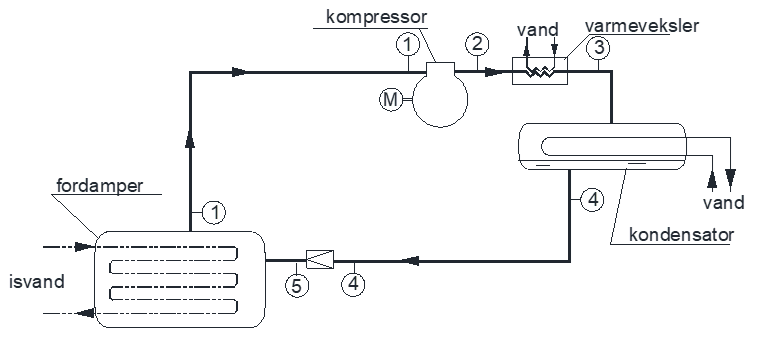

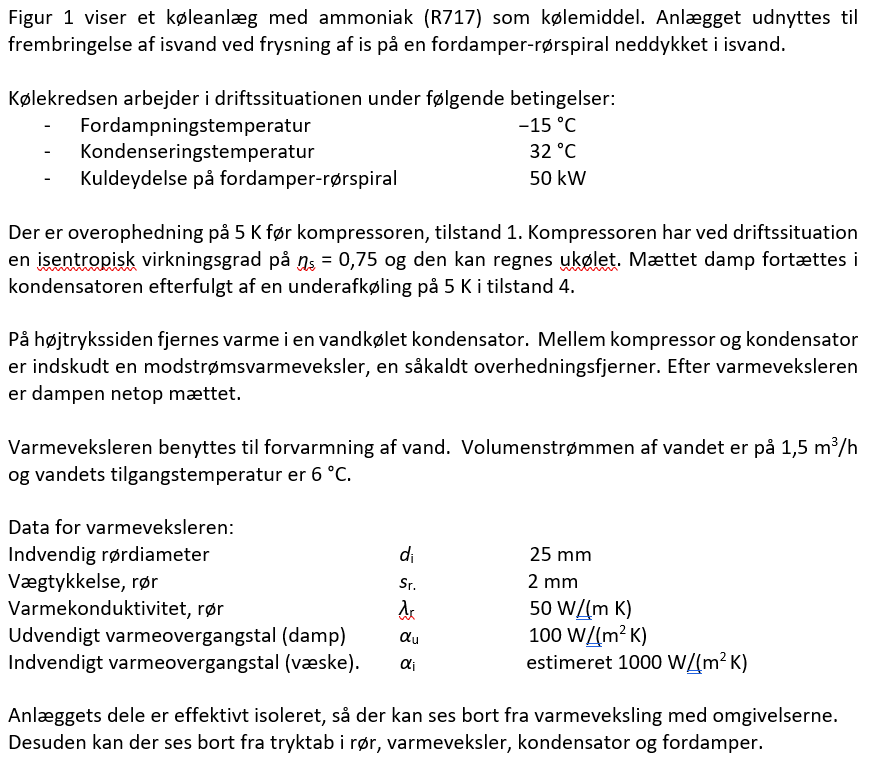

### a) Indtegn processen i log *p,h*-diagrammet, bilag 2. Diagrammet afleveres med løsningen

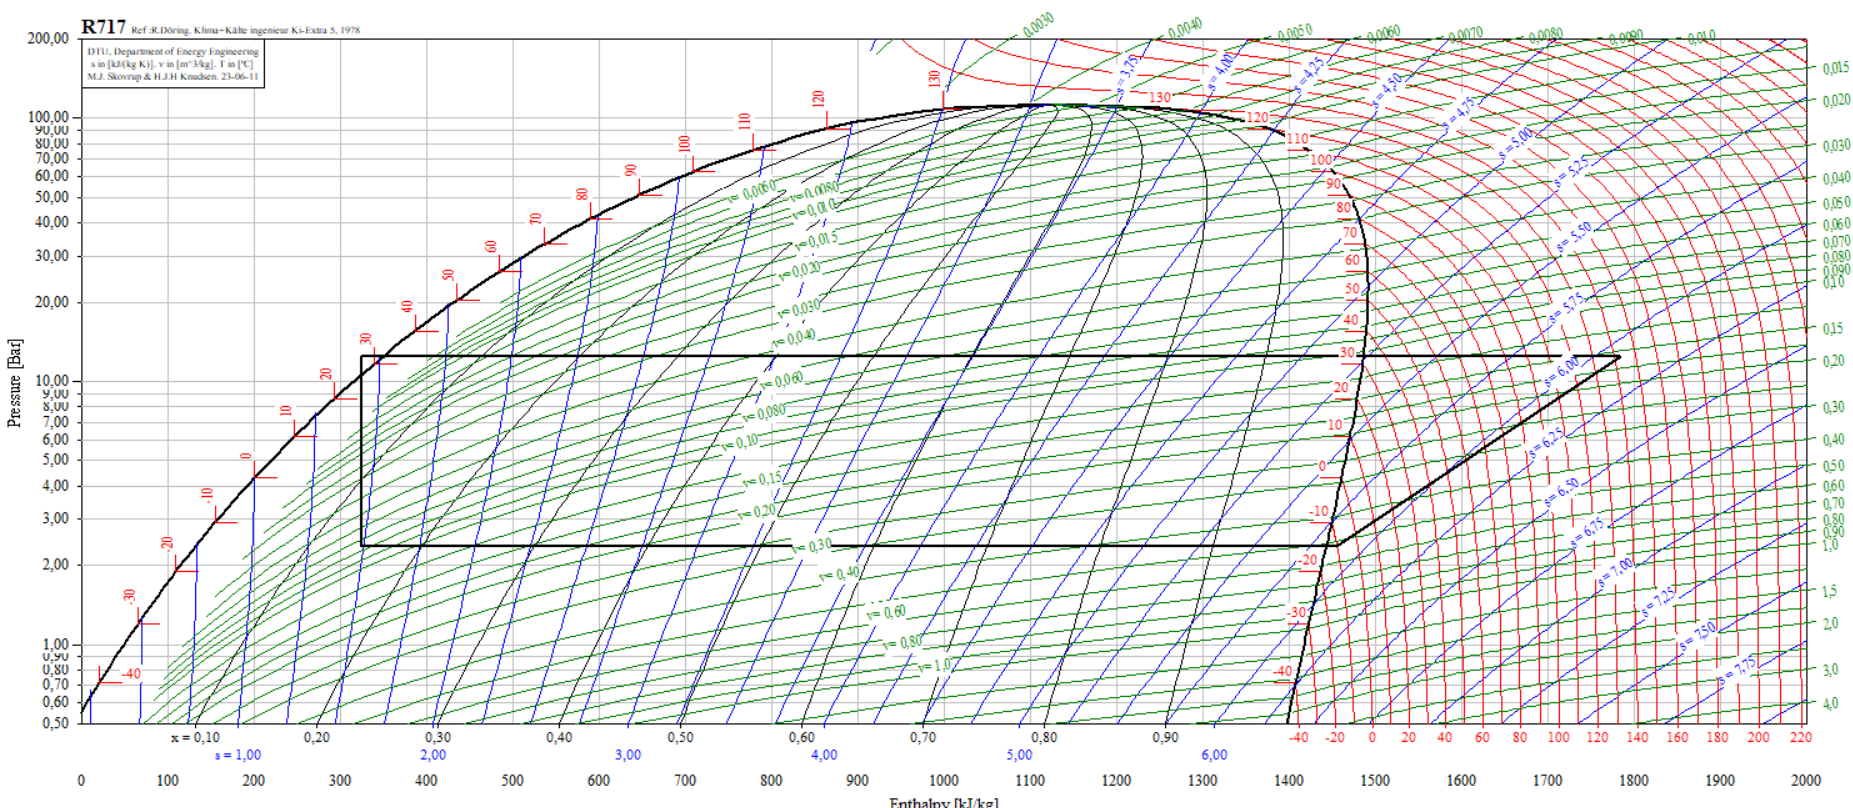

### b) Trykkene i henholdsvis fordamper og kondensator [bar]

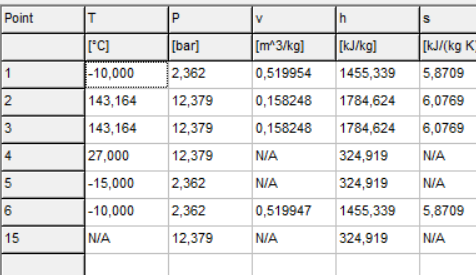

clear all
clf
% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'R717';


P_1 = 2.362 * 1e5; % Pa
P_2 = 12.379 * 1e5;  % Pa
P_3 = P_2;
P_4 = P_2;
P_5 = P_1;

### c) Massestrømmen af kølemiddel R717 i køleanlægget [kg/h]

T_2 = 143.164 + 273.15;
T_4 = 32 - 5 + 273.15;
T_3 = 32 + 273.15;
T_5 = -15 + 273.15;

h_1 = 1455.339 * 1e3;
h_2 = 1784.624 * 1e3;
h_4 = 324.919 * 1e3;
h_5 = h_4;

Phi_0 = 50 * 1e3;

syms q_mR
eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0

$$eq\_energi\_4 = 50000-1130420\,q_{\mathrm{mR}}=0$$

q_mR = vpasolve(eq_energi_4, q_mR)

$$q\_mR = 0.044231347640699916845066435484156$$

q_mR_H = q_mR * 3600

$$q\_mR\_H = 159.23285150651970064223916774296$$

### d) Varmeydelsen overført i varmeveksleren [kW]

% h_3 = CoolProp.PropsSI('H', 'P', P_3, 'T', T_3, fluid)%, 'Q', 1, fluid)
h_3 = 1488.4 * 1e3;
syms Phi_VV
eq_energi_2 = q_mR * (h_2 - h_3) - Phi_VV == 0

$$eq\_energi\_2 = 13102.386723518692167512959784859-\Phi_{\mathrm{VV}}=0$$

Phi_VV = vpasolve(eq_energi_2, Phi_VV)

$$Phi\_VV = 13102.386723518692167512959784859$$

### e) Den nødvendige rørlængde i varmeveksleren [m] baseret på de angivne lednings- og varmeovergangstal

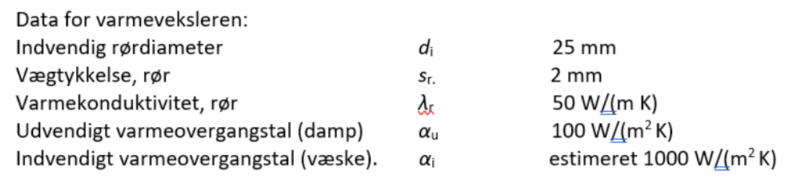

brug alternetivt 

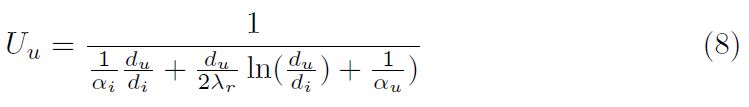

for rør

d_i = 0.025;
delta = 0.002;
lambda_ror = 50;
alpha_u = 100;
alpha_i = 1000;



T_vand_min = 6 + 273.15;

c_p_vand = CoolProp.PropsSI('C', 'P', 1e5, 'T', T_vand_min, 'Water')

c_p_vand = 4.2028e+03

rho_p_vand = CoolProp.PropsSI('D', 'P', 1e5, 'T', T_vand_min, 'Water')

rho_p_vand = 999.9423

qV_vand = 1.5/3600;

T_vand_max = T_vand_min + Phi_VV/(c_p_vand * rho_p_vand * qV_vand)

$$T\_vand\_max = 286.63259834937290537997519015156$$

syms L
d_u = d_i + 2*delta

d_u = 0.0290

A_u = pi * d_u * L

$$A\_u = \frac{29\,\pi \,L}{1000}$$

R_u = 1 / (alpha_u * A_u) % K/W

$$R\_u = \frac{10}{29\,L\,\pi }$$

r_u = d_u/2;
r_i = d_i/2;
R_r = (r_u / r_i) / (lambda_ror * 2 * pi * L)

$$R\_r = \frac{29}{2500\,L\,\pi }$$

A_i = pi * d_i * L

$$A\_i = \frac{\pi \,L}{40}$$

delta_t_max = T_2 - T_vand_max

$$delta\_t\_max = 129.68140165062705914973144070423$$

delta_t_min = T_3 - T_vand_min

delta_t_min = 26

LMTD = (delta_t_max - delta_t_min) / log(delta_t_max / delta_t_min)

$$LMTD = 64.51924357022452392740599925942$$

R_i = 1 / (alpha_i * A_i) % K/W

$$R\_i = \frac{1}{25\,L\,\pi }$$

R_tot = R_u + R_r + R_i

$$R\_tot = \frac{28741}{72500\,L\,\pi }$$

% R_tot2 = ((T_2 + T_3)/2 - T_vand) / Phi_VV
UA = 1/R_tot;
eq_1 = UA * LMTD

$$eq\_1 = 162.75164951954622263445721952291\,\pi \,L$$

eq_L = solve(eq_1 == Phi_VV, L)

$$eq\_L = 25.625664864295952507563719102415$$

 Længden er sålede $25,6$m

### f) Beskriv (uden detaljerede beregninger) en metode undersøgelse af, om det indvendige varmeovergangstal er *α*i  er estimeret korrekt

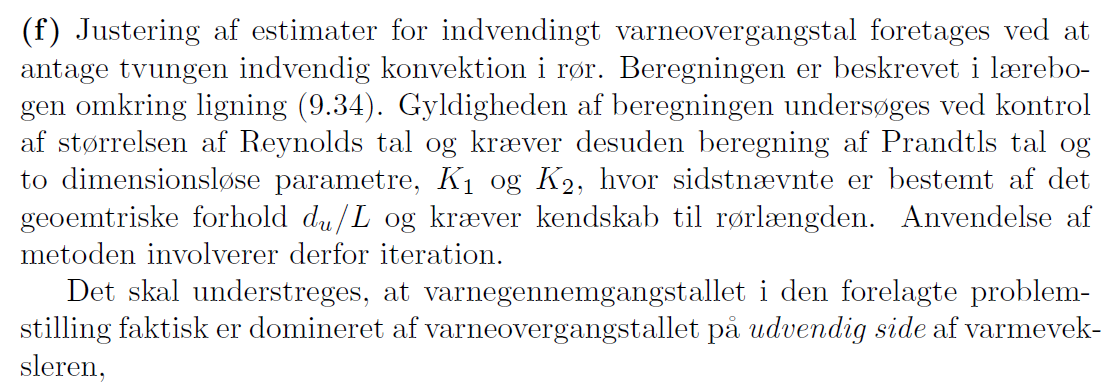

clear all
clf
% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'Air';

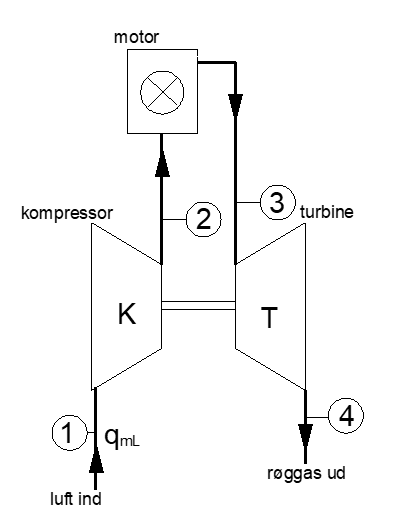

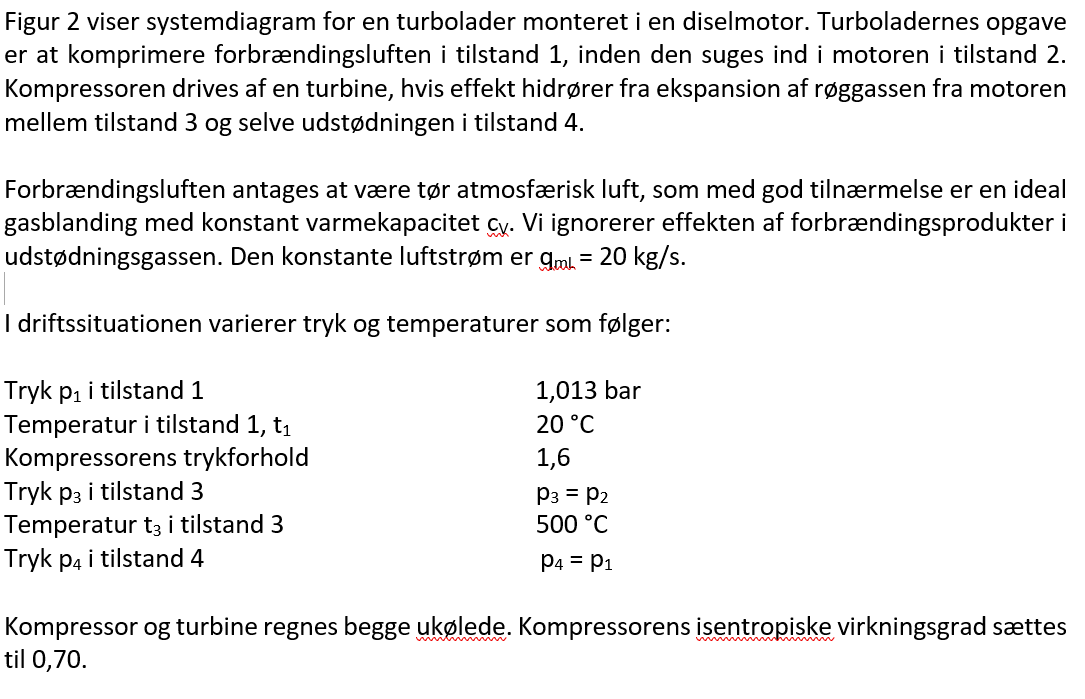

### a) Opstil energibalancer på kompressor og turbine

syms q_mL h_1 h_2 h_3 h_4 Phi_K Phi_0 P_K P_T P_el

% eq_energi_komp = q_mL * (h_1 - h_2) + P_K == 0 % kompressor


$$P_{K}+q_{\mathrm{mL}}\,\left(h_{1}-h_{2}\right)=0$$


eq_energi_3 = q_mL * (h_3 - h_4) - P_T == 0 % Turbine

$$eq\_energi\_3 = q_{\mathrm{mL}}\,\left(h_{3}-h_{4}\right)-P_{T}=0$$


$$q_{\mathrm{mL}}\,\left(h_{3}-h_{4}\right)-P_{T}=0$$


q_mL = 20;
P_1 = 101300;
T_1 = 20 +273.15;
Tyrk_forhold_komp = 1.6;
P_2 = Tyrk_forhold_komp * P_1

P_2 = 162080

P_3 = P_2;
P_4 = P_1

P_4 = 101300

T_3 = 500 + 273.15;
eta_motor = 0.70;

### b) Bestem den tilførte akseleffekt til kompressoren

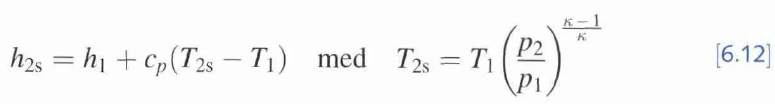

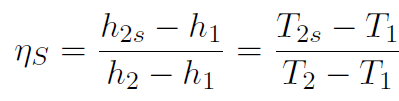

Vi finder først $\kappa$ for luft

c_p_luft = CoolProp.PropsSI('C', 'P', P_1, 'T', T_1, 'Air')

c_p_luft = 1.0061e+03

c_v_luft = CoolProp.PropsSI('O', 'P', P_1, 'T', T_1, 'Air')

c_v_luft = 717.6655

kappa = c_p_luft/c_v_luft

kappa = 1.4020

T_2s = T_1 * (Tyrk_forhold_komp)^((kappa - 1)/kappa)

T_2s = 335.4397


% h_1 = CoolProp.PropsSI('H', 'P', P_1, 'T', T_1, 'Air')

h_1 = 4.1940e+05


% h_2s = h_1 + c_p_luft * (T_2s - T_1)

h_2s = 4.6195e+05


syms T_2
T_2_eq = eta_motor == (T_2s - T_1)/(T_2 - T_1);
% h_2_eq = (h_2s - h_1)/(h_2 - h_1) == (T_2s - T_1)/(T_2 - T_1);

T_2  = vpasolve(T_2_eq, T_2)

$$T\_2 = 353.56390095437642620319300996406$$

$$h\_2 = 480190.04187849519075825810432434$$

P_K = q_mL * c_p_luft * (T_2 - T_1)

$$P\_K = 1215701.2142782917544445865460056$$

$$P\_A = 1215701.2142782917544445865460056$$

### c) Bestem turbinens isentropiske virkningsgrad

### d) Bestem tryk, temperatur, specifikt gasvolumen og specifik entalpi i tilstande hvor data ikke allerede er opgivet.

### e) Skitser luftens processer fra tilstand 1 til 4 i *T,s*-diagram